#### Triple Integrals 

#### Ex.1 Evaluate$\int_0^1 \int_0^{x^2 } \int_0^{x+y} \left(x-2y+z\right)\mathrm{dzdydx}\;$

syms x y z
ans1 = int(int(int(x - 2*y + z,z,0,x + y),y,0,x^2),x,0,1)

$$ans1 = \frac{8}{35}$$

Ex.2 Evaluate $\int_0^1 \int_0^{\sqrt{1-x^2 }} \int_0^{\sqrt{1-x^2 -y^2 }} \frac{\mathrm{dzdydx}}{\sqrt{1-x^2 -y^2 -z^2 }}$

syms x y z
ans2 = int(int(int(1/sqrt(1-x^2-y^2-z^2),z,0,sqrt(1-x^2-y^2)),y,0,sqrt(1-x^2)),x,0,1)

$$ans2 = \frac{\pi^{2}}{8}$$

EX.3 Evaluate $\int \int \int y\;\mathrm{sin}\left(x\right)+\mathrm{zcos}\left(x\right)$  over the region $0 \le x \le \pi$, $0 \le y \le 1$, and $-1 \le z \le 1$.

fun = @(x,y,z) y.*sin(x)+z.*cos(x) %function of 3 variables

fun = function_handle with value:
    @(x,y,z)y.*sin(x)+z.*cos(x)


Integral_value= integral3(fun,0,pi,0,1,-2,2)

Integral_value = 4.0000

Ex 4: Evaluate $\int_{-1}^1 \int_0^z \int_{x-z}^{x+z} \left(x+y+z\right)\mathrm{dxdydz}$

K = @(x,y,z) x+y+z

K = function_handle with value:
    @(x,y,z)x+y+z


%difine limits of integration in cartesian co-ord
zmin = -1;
zmax = 1;
ymin = 0;
ymax = @(z) z;
xmin = @(x,z) x-z;
xmax = @(x,z) x+z;
Value = integral3(K,zmin,zmax,ymin,ymax,xmin,xmax)

Value = -1.1102e-16

#### Ex. 5 Suppose the temperature at a point is given by T=xyz. Find the average temperature in the cube with opposite cornors at (0,0,0) and (2,2,2)

clear vars
syms x y z
avertemp=int(int(int(x*y*z,0,2),0,2),0,2)

$$avertemp = 8$$

#### Ex.6 Find the volume of the cylinder $x^2 +y^2 =a^2$;  z=0; z=h.

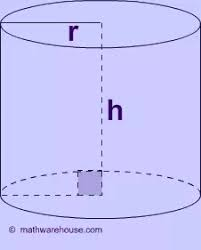

syms x y z a h
V=4*int(int(int(1,z,0,h),y,0,sqrt(a^2-x^2)),x,0,a)

$$V = \pi \,a^{2}\,h$$

#### Ex.7 Find the volume of the solid common to the two cylinder $x^2 +y^2 {=a}^2 ,\;\;x^2 +z^2 =a^2$

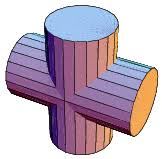

clear vars
syms x y z a
volofsolid=8*int(int(int(1,z,0,sqrt(a^2-x^2)),y,0,sqrt(a^2-x^2)),x,0,a)

$$volofsolid = \frac{16\,a^{3}}{3}$$

#### Ex.8 Find the volume of the portion of the sphere $x^2 +y^2 +z^2 =a^2$ lying inside the cylinder $x^2 +y^2 =\mathrm{ax}$

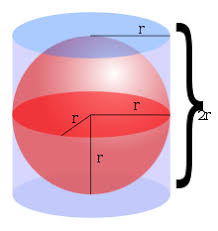

syms r theta z a
volportion=4*int(int(int(z,0,sqrt(a^2-r^2)),r,0,a*cos(theta)),theta,0,pi/2)

$$volportion = \frac{14\,a^{3}}{9}$$

fun = @(x,y,z) x.*cos(y) + x.^2.*cos(z)

fun = function_handle with value:
    @(x,y,z)x.*cos(y)+x.^2.*cos(z)


Ex 9: Triple integral over  the region (over the sphere with radius 1 unit)

%difine limits of integration in cartesian co-ord
xmin = -1;
xmax = 1;
ymin = @(x)-sqrt(1 - x.^2);
ymax = @(x) sqrt(1 - x.^2);
zmin = @(x,y)-sqrt(1 - x.^2 - y.^2);
zmax = @(x,y) sqrt(1 - x.^2 - y.^2);
Ans = integral3(fun,xmin,xmax,ymin,ymax,zmin,zmax)

Ans = 0.7796

#### Ex 10: Find the volume of the tetrahedron bounded by the plane passing through the points A(1,0,0), B(0,2,0), C(0,0,3) and the three coordinate planes .

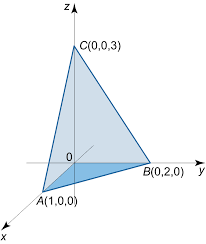

syms x y z real
f=1 %integrand

f = 1

%limits of int since eqn of plane is 6x+3y+2z=6
xmin=0;
xmax=1;
ymin=0;
ymax=2-2*x;
zmin=0;
zmax=3-3*x-(3/2)*y;
I1=int(f,z,zmin,zmax) %int w r t z

$$I1 = 3-\frac{3\,y}{2}-3\,x$$

I2=int(I1,y,ymin,ymax)% int w r t y

$$I2 = 3\,{\left(x-1\right)}^{2}$$

I3=int(I2,x,xmin,xmax)% int w r t x

$$I3 = 1$$

Vol=I3

$$Vol = 1$$

#### Ex 11 :Find the volume of the solid formed by two paraboloids:$z_1 =x^2 +y^2$ and  $z_2 =1-x^2 -y^2$

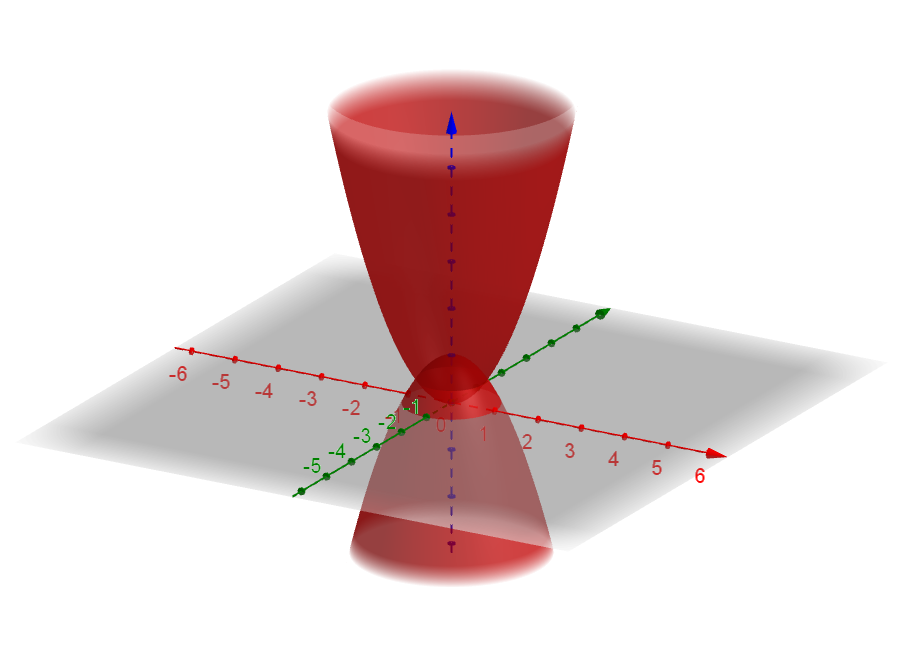

Ans: Volume=$\int \int \int \mathrm{dxdydz}$ in cartesian coordinates.

In cylindrical coordinates $\left(r,\theta ,z\right)$, $x^2 +y^2 =r^2$ so $z_1 =r^2 \text{\,}\mathrm{and}\text{\,}z_2 ={1-r}^2$ ,hence z varies from $r^2 \text{\,}\mathrm{to}\text{\,}1-r^2$, r varies from 0 to $\frac{1}{\sqrt{2}}$ and $\theta \text{\,}$varies from $0\text{\,}\mathrm{to}\text{\,}2\pi$

Volume=$\int_0^{2\pi } \int_0^{\frac{1}{\sqrt{2}}} \int_{r^2 }^{1-r^2 } \mathrm{rdzdrd}\theta$

syms r z theta real
fun=r

$$fun = r$$

zmin=r^2

$$zmin = r^{2}$$

zmax=1-r^2

$$zmax = 1-r^{2}$$

rmin=0

rmin = 0

rmax=1/sqrt(2)

rmax = 0.7071

thetamin=0

thetamin = 0

thetamax= 2*pi

thetamax = 6.2832

value=int(int(int(fun,z,zmin,zmax),r,rmin,rmax),theta,thetamin,thetamax)

$$value = \frac{\pi }{4}$$

solidvolume=double(abs(value))

solidvolume = 0.7854

#### Ex 12: Calculate the volume of the solid bounded by the paraboloid $z=2-x^2 -y^2$and the conic surface  $z=\sqrt{x^2 +y^2 }$

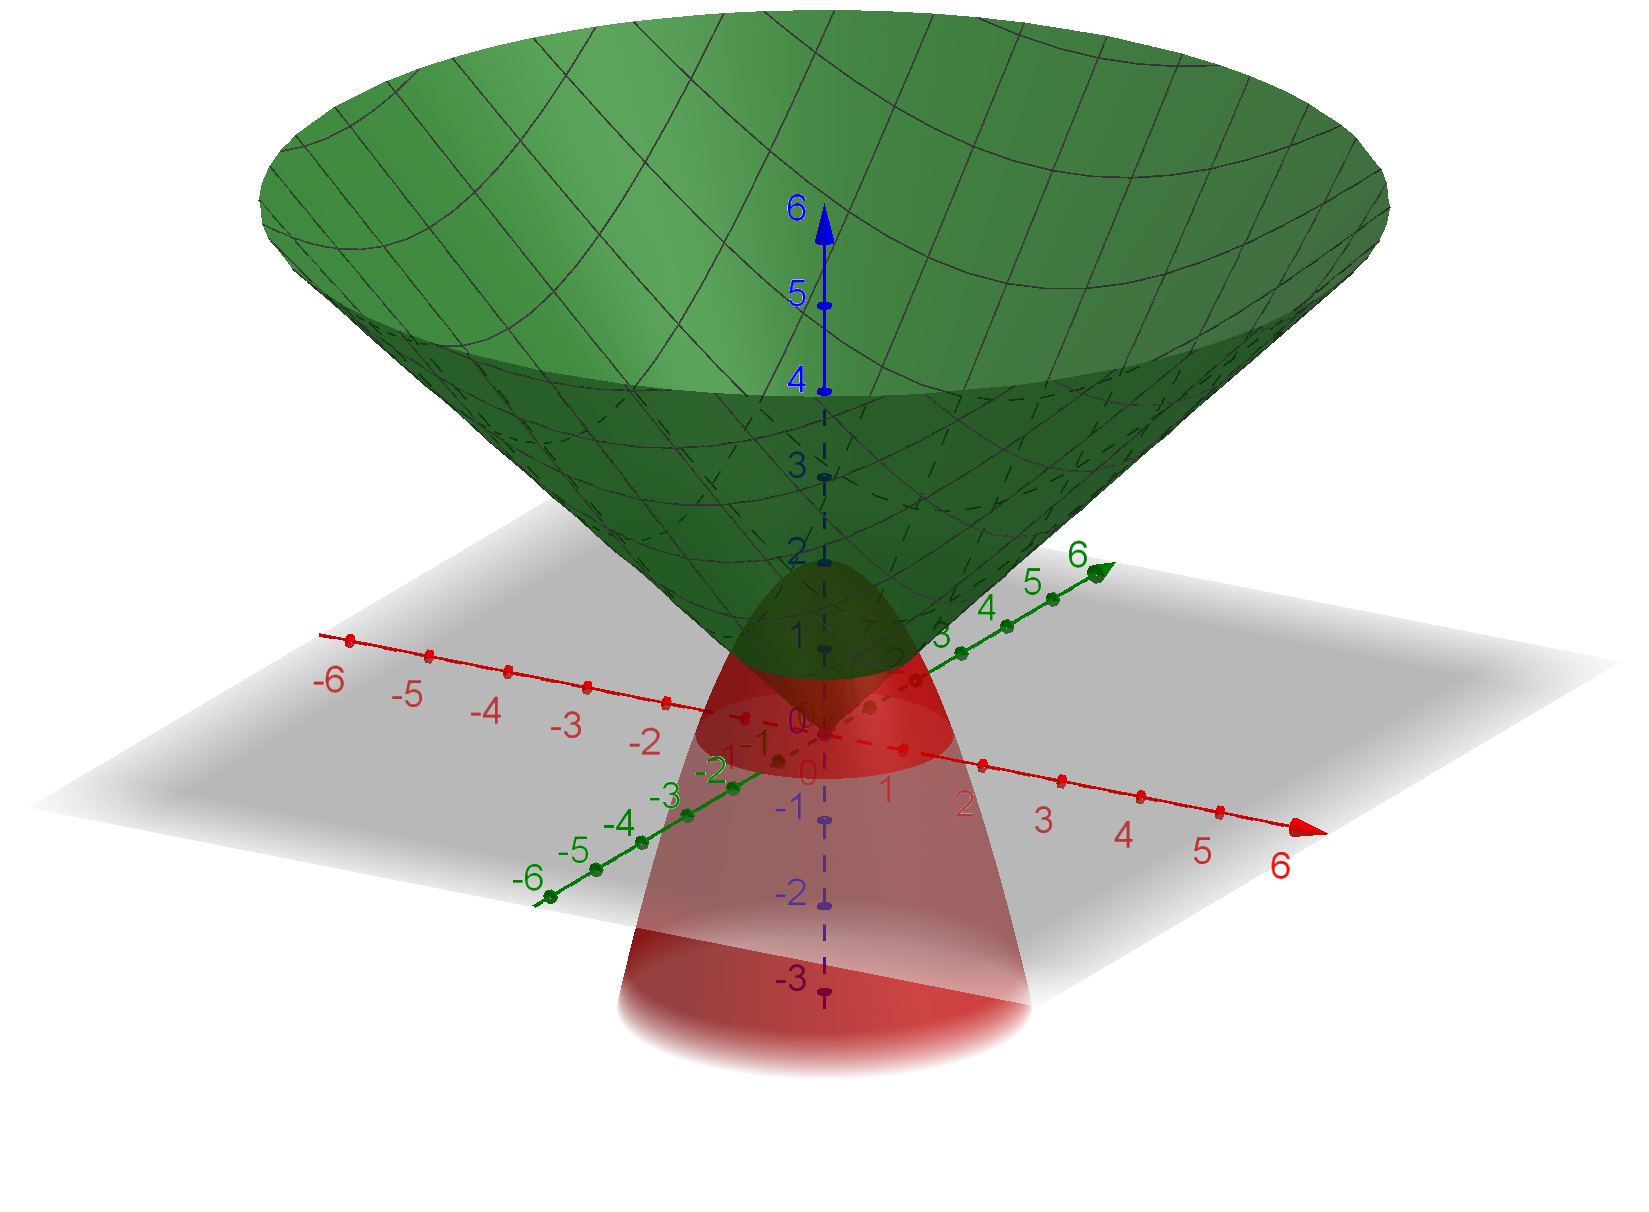

Ans: Intersection of both the surfaces is a circle $x^2 +y^2 =1$. The region of integration is bounded from above by the paraboloid, and from below by the cone.To calculate the volume of the solid we use cylindrical coordinates $\left(r,\theta ,z\right)$. 

Volume=$\int_0^{2\pi } \int_0^1 \int_r^{2-r^2 } \text{rdzdrd}\theta$

clear vars
syms r z theta real
f=r

$$f = r$$

zmin=r;
zmax=2-r^2;
rmin=0;
rmax=1;
thetamin=0;
thetamax= 2*pi;
value=int(int(int(f,z,zmin,zmax),r,rmin,rmax),theta,thetamin,thetamax)

$$value = \frac{5\,\pi }{6}$$

Volume_of_solid=double(abs(value))

Volume_of_solid = 2.6180

#### EX 13: A cube has sides of length 4. Let one corner be at the origin and the adjacent corners be on the positive x, y, and z axes.

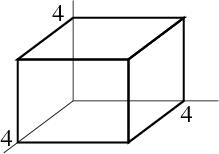

 If the cube's density is proportional to the distance from the $\mathrm{xyplane}\;$, Find its mass

solution :

The density of the cube is f(x,y,z)=kz for some constant  k

If W is the cube, the mass is the triple integral


$$\int \int \int_W \mathrm{kzdV}=\int_0^4 \int_0^4 \int_0^4 \mathrm{kzdzdydx}$$


syms x y z k
d=k*z

$$d = k\,z$$

m=int(int(int(d,z,0,4),y,0,4),x,0,4)

$$m = 128\,k$$

#### Ex. 15: Let W be the pyramid bounded by the planes

#### 
$$z=0,z=4-2x,z=2-y,z=2x\;\mathrm{and}\;z=2+y$$


#### Mass of the pyramid is the triple integral of the density which is  given by $\mathrm{∭f}\left(x,y,z\right)\mathrm{dV}$

From equations 


$$z=4-2x\mathrm{and}z=2x,z/2\le x\le 2-z/2$$


From equations $z=2-y\mathrm{and}z=2+y,z-2\le y\le 2-z$

The bottom of the pyramid is z=0 as that plane is one of the given boundaries. The top of the pyramid occurs where all four planes meet, which is when  z=2


$$z=0\;\mathrm{to}\;2$$
  

syms x y z
d=x*z

$$d = x\,z$$

xmin=z/2

$$xmin = \frac{z}{2}$$

xmax=2-(z/2)

$$xmax = 2-\frac{z}{2}$$

ymin=z-2

$$ymin = z-2$$

ymax=2-z

$$ymax = 2-z$$

mass=int(int(int(d,x,xmin,xmax),y,ymin,ymax),z,0,2)

$$mass = \frac{8}{3}$$

#### EX 16: Use cylindrical coordinates to find the volume of a curved wedge cut out from a cylinder ${\left(x-2\right)}^2 +y^2 =4$ by the planes $z=0\;\mathrm{and}\;z=-y$  ${\left(x-2\right)}^2 +y^2 =4$

sol:


$$\Rightarrow x^2 +y^2 =4x\longrightarrow \ast$$


cylindrical coordinates are r,$\theta ,z$

put $x=\mathrm{rcos}\theta ,y=\mathrm{rsin}\theta$ in $\ast$


$$r^2 =4\mathrm{rcos}\theta$$


r varies from 0 to $4\cos \theta ,$


$$\theta \;\mathrm{varies}\;\mathrm{from}\frac{3\pi }{2}\;\mathrm{to}\;2\pi$$



$$z\;\mathrm{varies}\;\mathrm{from}\;0\;\mathrm{to}-\mathrm{rsin}\theta$$


volume is given by V=$\int \int \int \mathrm{rdzdrd}\theta$

syms r z thetha
f=r

$$f = r$$

rmin=0

rmin = 0

rmax=4*(cos(thetha))

$$rmax = 4\,\cos\left(\mathrm{thetha}\right)$$

zmin=0

zmin = 0

zmax=-r*(sin(thetha))

$$zmax = -r\,\sin\left(\mathrm{thetha}\right)$$

thethamin=3*pi/2

thethamin = 4.7124

thethamax=2*pi

thethamax = 6.2832

v=int(int(int(f,z,zmin,zmax),r,rmin,rmax),thetha,thethamin,thethamax)

$$v = \frac{16}{3}$$

#### Ex17.Find  the volume of the region bounded by the cone$z=\sqrt{3\left(x^2 +y^2 \right)}$ and the hemisphere $z=\sqrt{\left(4-x^2 -y^2 \right)}$

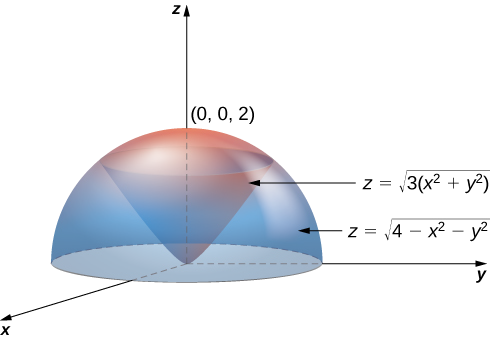

 Using the conversion formulas from rectangular $x=\rho \mathrm{sin}\varphi \mathrm{cos}\theta ,y=\rho \mathrm{sin}\varphi \mathrm{sin}\theta ,z=\rho \mathrm{cos}\varphi$coordinates to spherical coordinates, we have:

For the cone:$z=\sqrt{3\left(x^2 +y^2 \right)}$$\rho \mathrm{cos}\varphi =\sqrt{3}\rho \mathrm{sin}\varphi \Rightarrow \mathrm{tan}\varphi =\frac{1}{\sqrt{3}}\Rightarrow \varphi =\frac{\pi }{6}$

from the sphere $\rho =2$

and $\theta \;\mathrm{varies}\;\mathrm{from}\;0\;\mathrm{to}\;2\pi$

the volume is given by the triple integral 


$$V=\int \int \int_E \rho^2 \mathrm{sin}\varphi d\varphi d\theta d\rho$$


syms rho thetha phi
f=(rho^2*sin(phi))

$$f = \rho^{2}\,\sin\left(\phi \right)$$

rhomin=0

rhomin = 0

rhomax=2

rhomax = 2

thethamin=0

thethamin = 0

thethamax=2*pi

thethamax = 6.2832

phimin=0

phimin = 0

phimax=(pi)/6

phimax = 0.5236

volume=int(int(int(f,rho,rhomin,rhomax),thetha,thethamin,thethamax),phi,phimin,phimax)

$$volume = -\frac{8\,\pi \,\left(\sqrt{3}-2\right)}{3}$$

#### Ex-1. Consider a spherical ring, which is a sphere with a cylindrical hole cut so that the axis

#### of the cylinder passes through the center of the sphere (see the following figure).

#### (a) If the sphere has radius 4 and the cylinder has radius 2 find the volume of the spherical ring.

#### (b) A cylindrical hole of diameter 6 cm is bored through a sphere of radius 5 cm such that the axis of the cylinder passes through the center of the sphere. Find the volume of the resulting spherical ring.

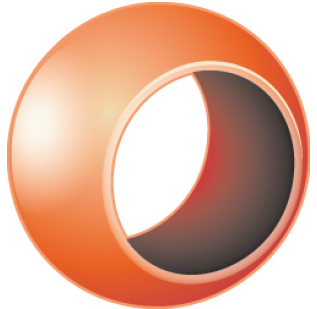

Solution:

 V=Vol of sphere-Vol of cylinder-2(vol of one of the spherical caps)

Let R=radius of a sphere and r=radius of  a cylinder 

The following are standard:

Vol of sphere=$\frac{4}{3}\Pi R^3$

Vol of cylinder= $\Pi {\textrm{hr}}^2$

Vol of one of the spherical caps=$\int_V \mathrm{dzdydx}$

(a)

syms x y z
R=4

R = 4

V1=4/3*pi*R^3

V1 = 268.0826

r=2

r = 2

h=4*sqrt(3)

h = 6.9282

V2=pi*h*r^2

V2 = 87.0624

% volume of one of the spherical caps is
%V3=int(int(int(1,z,2*sqrt(3),sqrt(16 - x^2 - y^2),y,-sqrt(4 - x^2),sqrt(4 - x^2),x,-2,2)))
f=1

f = 1

I1=int(f,z,2*sqrt(3),sqrt(16-x^2-y^2))

$$I1 = \sqrt{-x^{2}-y^{2}+16}-2\,\sqrt{3}$$

I2=int(I1,y,-sqrt(4-x^2),sqrt(4-x^2))

$$I2 = \sqrt{12}\,\sqrt{4-x^{2}}-4\,\sqrt{3}\,\sqrt{4-x^{2}}-2\,\mathrm{asin}\left(\frac{\sqrt{4-x^{2}}}{\sqrt{16-x^{2}}}\right)\,\left(\frac{x^{2}}{2}-8\right)$$

I3=int(I2,x,-2,2)

$$I3 = \int_{-2}^{2}\left(\sqrt{12}\,\sqrt{4-x^{2}}-4\,\sqrt{3}\,\sqrt{4-x^{2}}-2\,\mathrm{asin}\left(\frac{\sqrt{4-x^{2}}}{\sqrt{16-x^{2}}}\right)\,\left(\frac{x^{2}}{2}-8\right)\right)\mathrm{d}x$$

V3=double(I3)

V3 = 3.4477

ansa=V1-V2-2*V3

ansa = 174.1247

(b)

syms x y z
R=5

R = 5

V1=4/3*pi*R^3

V1 = 523.5988

r=3

r = 3

h=8

h = 8

V2=pi*h*r^2

V2 = 226.1947

% volume of one of the spherical caps is
f=1

f = 1

I1=int(f,z,4,sqrt(25-x^2-y^2))

$$I1 = \sqrt{-x^{2}-y^{2}+25}-4$$

I2=int(I1,y,-sqrt(9-x^2),sqrt(9-x^2))

$$I2 = -2\,\mathrm{asin}\left(\frac{\sqrt{9-x^{2}}}{\sqrt{25-x^{2}}}\right)\,\left(\frac{x^{2}}{2}-\frac{25}{2}\right)-4\,\sqrt{9-x^{2}}$$

I3=int(I2,x,-3,3)

$$I3 = \int_{-3}^{3}\left(-2\,\mathrm{asin}\left(\frac{\sqrt{9-x^{2}}}{\sqrt{25-x^{2}}}\right)\,\left(\frac{x^{2}}{2}-\frac{25}{2}\right)-4\,\sqrt{9-x^{2}}\right)\mathrm{d}x$$

V3=double(I3)

V3 = 14.6608

Volume=V1-V2-2*V3

Volume = 268.0826